Precession of a fictitious celestial object:

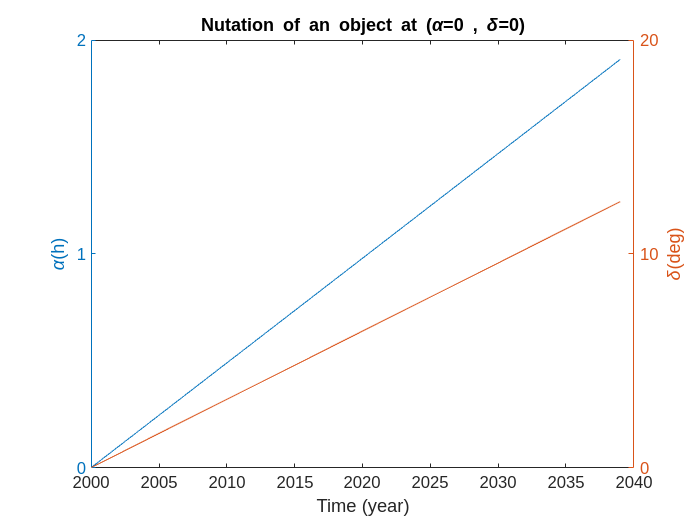

deltas = [];
alphas = [];
% coordinates of a fictitious celestial object at the vernal equinox
alpha = 0;
delta = 0;
% Converted to Cartesian
xi0 = [];
[xi0(1),xi0(2),xi0(3)] = spherical_to_cartesian(delta, alpha, 1);
xi0 = xi0.';
% Resolution
yyyy=2000:2039;
mm=1;
dd=1; ut1=12; minute=0; second=0;
for y=yyyy
    % Calculate Julian Day
    curr_jd = gre2jd(y,mm,dd,ut1,minute,second);
    % Calculate The nutation matrix
    nut_mat = precession(curr_jd);
    % Multiply with vector
    xip = nut_mat * xi0;
    % Convert back to Celestial coordinates in original units
    [delta_res, alpha_res, radi] = cartesian_to_spherical(xip(1), xip(2), xip(3));
    deltas(end+1) = rad2deg(delta_res);
    alphas(end+1) = rad2deg(alpha_res)/15;
end
[hAx,hLine1,hLine2] = plotyy(yyyy, alphas, yyyy, deltas);
title("Nutation of an object at (\alpha=0 , \delta=0)");
ylabel(hAx(1),"\alpha(h)") % left y-axis 
ylabel(hAx(2),"\delta(deg)") % right y-axis
xlabel(hAx, "Time (year)")

Nutation of a fictitious celestial object:

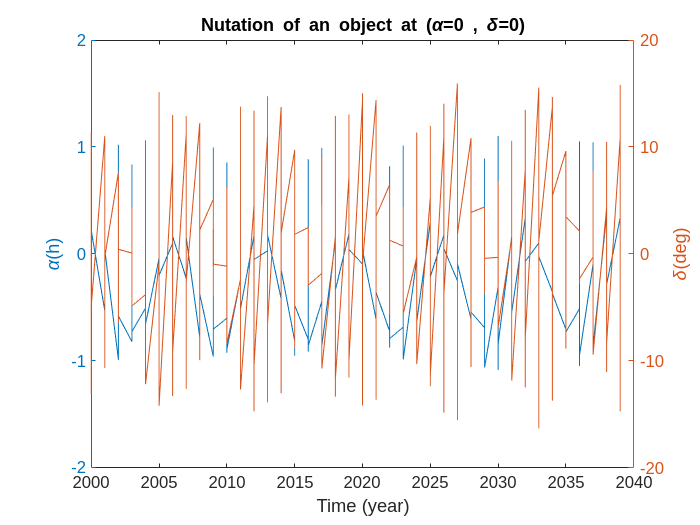

deltas = [];
alphas = [];
% coordinates of a fictitious celestial object at the vernal equinox
alpha = 0;
delta = 0;
% Converted to Cartesian
xi0 = [];
[xi0(1),xi0(2),xi0(3)] = spherical_to_cartesian(delta, alpha, 1);
xi0 = xi0.';
% Resolution
yyyy=2000:2039;
mm=1:12;
dd=1; ut1=12; minute=0; second=0;
for y=yyyy
    for m=mm
        % Calculate Julian Day
        curr_jd = gre2jd(y,m,dd,ut1,minute,second);
        % Calculate The nutation matrix
        nut_mat = nutation(curr_jd);
        % Multiply with vector
        xip = nut_mat * xi0;
        % Convert back to Celestial coordinates in original units
        [delta_res, alpha_res, radi] = cartesian_to_spherical(xip(1), xip(2), xip(3));
        deltas(end+1) = rad2deg(delta_res);
        alphas(end+1) = rad2deg(alpha_res)/15;
    end
end
x = repelem(yyyy,12);
[hAx,hLine1,hLine2] = plotyy(x, alphas, x, deltas);
title("Nutation of an object at (\alpha=0 , \delta=0)");
ylabel(hAx(1),"\alpha(h)") % left y-axis 
ylabel(hAx(2),"\delta(deg)") % right y-axis
xlabel(hAx, "Time (year)")